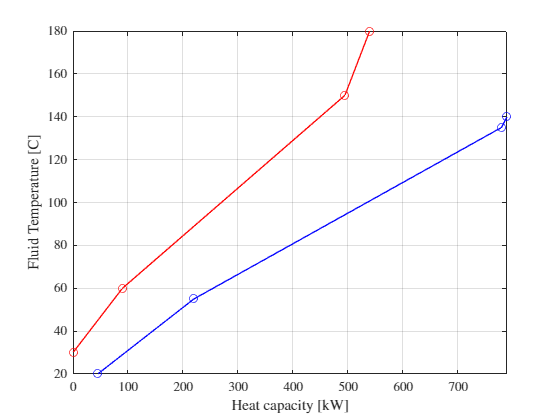

clc; clear

mcp_v1 = 3;
Tv1_ind = 180;
Tv1_ud = 60;

mcp_v2 = 1.5;
Tv2_ind = 150;
Tv2_ud = 30;

mcp_k1 = 5;
Tk1_ind = 20;
Tk1_ud = 135;

mcp_k2 = 2;
Tk2_ind = 55;
Tk2_ud = 140;

% Hot Heat flows
Qv1 = mcp_v1 * (Tv1_ind - Tv2_ind);
Qv2 = (mcp_v1 + mcp_v2) * (Tv2_ind - Tv1_ud);
Qv3 = mcp_v2 * (Tv1_ud - Tv2_ud);
Qv4 = mcp_v1 * (Tv1_ind - Tv2_ud);

% Cold Heat flows
Qk1 = mcp_k1 * abs(Tk1_ind - Tk2_ind);
Qk2 = (mcp_k1 + mcp_k2) * abs(Tk2_ind - Tk1_ud);
Qk3 = mcp_k2 * abs(Tk1_ud - Tk2_ud);
Qk4 = mcp_k1 * abs(Tk1_ind - Tk2_ud);

% Summing
Tvs = [Tv1_ind, Tv2_ind, Tv1_ud, Tv2_ud];
Tks = [Tk1_ind, Tk2_ind, Tk1_ud, Tk2_ud];
Qvs = cumsum([0, Qv1, Qv2, Qv3]);
Qks = cumsum([45, Qk1, Qk2, Qk3]);

figure
box on
hold on
plot(Qvs, fliplr(Tvs),"o-","color","red")
plot(Qks, Tks,"o-","Color","blue")
hold off
grid()
xlabel("Heat capacity [kW]")
ylabel("Fluid Temperature [C]")
xlim([min([Qvs, Qks]),max([Qvs, Qks])])